## Name:

## Date:

## PID: 

# Assignment 4 : Numerical Integration

**General Instructions:** Complete each question to the best of your abilities.  Include comments in your code to explain your thought process while answering.

Question 1 (15%): 

For function:


$$y=\ln \left(x\right)+\sin \left(3x\right)$$


a) (5%) Find the derivative using forward finite differences with a $h=0\ldotp 01$ from $x=0\ldotp 5$ to $6$.

clear,clc,close all
y=@(x) log(x)+sin(3*x);
df=@(x) 1./x + 3*cos(3*x);
h=0.01;
x=0.5:h:6;
% Method 1 - Difference Formula
dFForward1=(y(x(2:end))-y(x(1:end-1)))./h

dFForward1 =     2.1476    2.0192    1.8922    1.7666    1.6424    1.5197    1.3983    1.2784    1.1600    1.0430    0.9276    0.8137    0.7015    0.5908    0.4818    0.3746    0.2690    0.1653    0.0634   -0.0366   -0.1347   -0.2308   -0.3249   -0.4170   -0.5069   -0.5947   -0.6803   -0.7637   -0.8448   -0.9236   -1.0000   -1.0740   -1.1456   -1.2147   -1.2812   -1.3453   -1.4067   -1.4656   -1.5217   -1.5752   -1.6261   -1.6741   -1.7195   -1.7620   -1.8018   -1.8387   -1.8729   -1.9041   -1.9326   -1.9581


% Method 2 - Diff(x)
dFForward2=diff(y(x))./diff(x)

dFForward2 =     2.1476    2.0192    1.8922    1.7666    1.6424    1.5197    1.3983    1.2784    1.1600    1.0430    0.9276    0.8137    0.7015    0.5908    0.4818    0.3746    0.2690    0.1653    0.0634   -0.0366   -0.1347   -0.2308   -0.3249   -0.4170   -0.5069   -0.5947   -0.6803   -0.7637   -0.8448   -0.9236   -1.0000   -1.0740   -1.1456   -1.2147   -1.2812   -1.3453   -1.4067   -1.4656   -1.5217   -1.5752   -1.6261   -1.6741   -1.7195   -1.7620   -1.8018   -1.8387   -1.8729   -1.9041   -1.9326   -1.9581


b) (5%) Find the derivative using central finite differences with a $h=0\ldotp 01$ from $x=0\ldotp 5$ to $6$.

% Method 1 - Difference Formula
dFCentral1=(y(x(3:end))-y(x(1:end-2)))/(2*h)'

dFCentral1 =     2.0834    1.9557    1.8294    1.7045    1.5811    1.4590    1.3384    1.2192    1.1015    0.9853    0.8707    0.7576    0.6461    0.5363    0.4282    0.3218    0.2172    0.1144    0.0134   -0.0856   -0.1828   -0.2779   -0.3710   -0.4620   -0.5508   -0.6375   -0.7220   -0.8043   -0.8842   -0.9618   -1.0370   -1.1098   -1.1801   -1.2480   -1.3133   -1.3760   -1.4361   -1.4936   -1.5485   -1.6007   -1.6501   -1.6968   -1.7407   -1.7819   -1.8203   -1.8558   -1.8885   -1.9184   -1.9454   -1.9695


% Method 2 - Gradient
dFCentral2=gradient(y(x),x);

c) (5%) Plot the result from (a), (b), and the analytically found derivative in a 1 by 3 plot (1 row 3 columns) using [subplot](https://www.mathworks.com/help/matlab/ref/subplot.html).

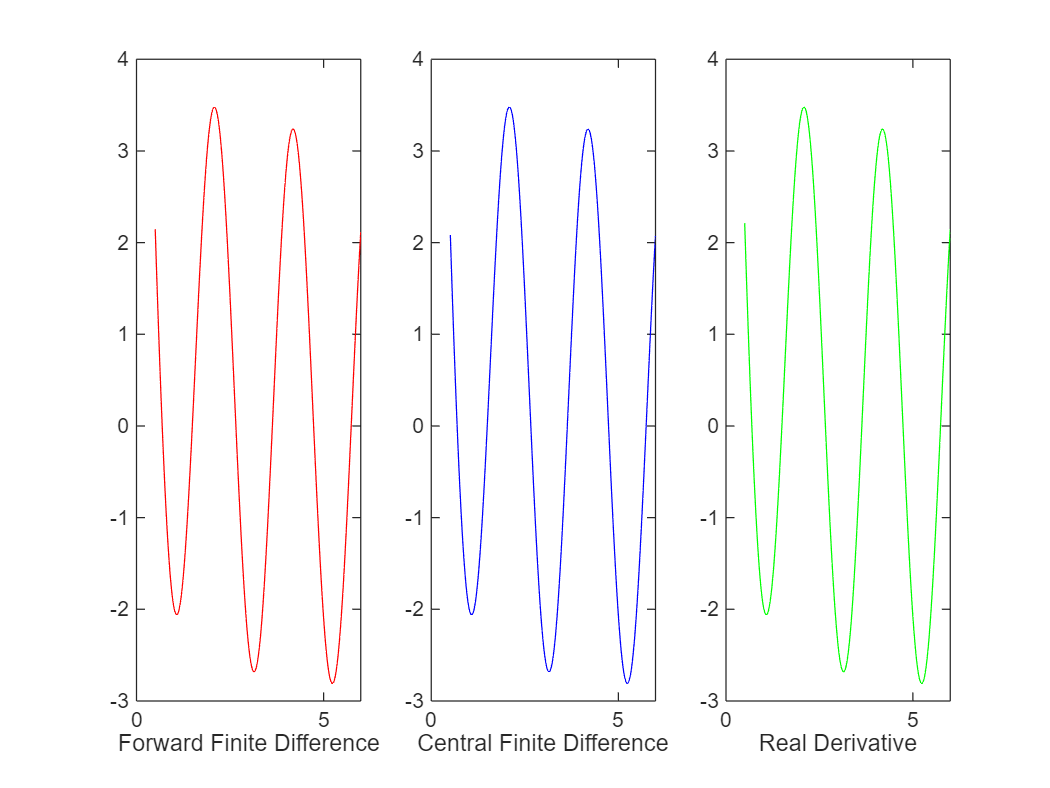

%Plotting
subplot(1,3,1)
plot(x(1:end-1),dFForward1,'r')
xlabel('Forward Finite Difference')
subplot(1,3,2)
plot(x(2:end-1),dFCentral1,'b')
xlabel('Central Finite Difference')
subplot(1,3,3)
plot(x,df(x),'g')
xlabel('Real Derivative')

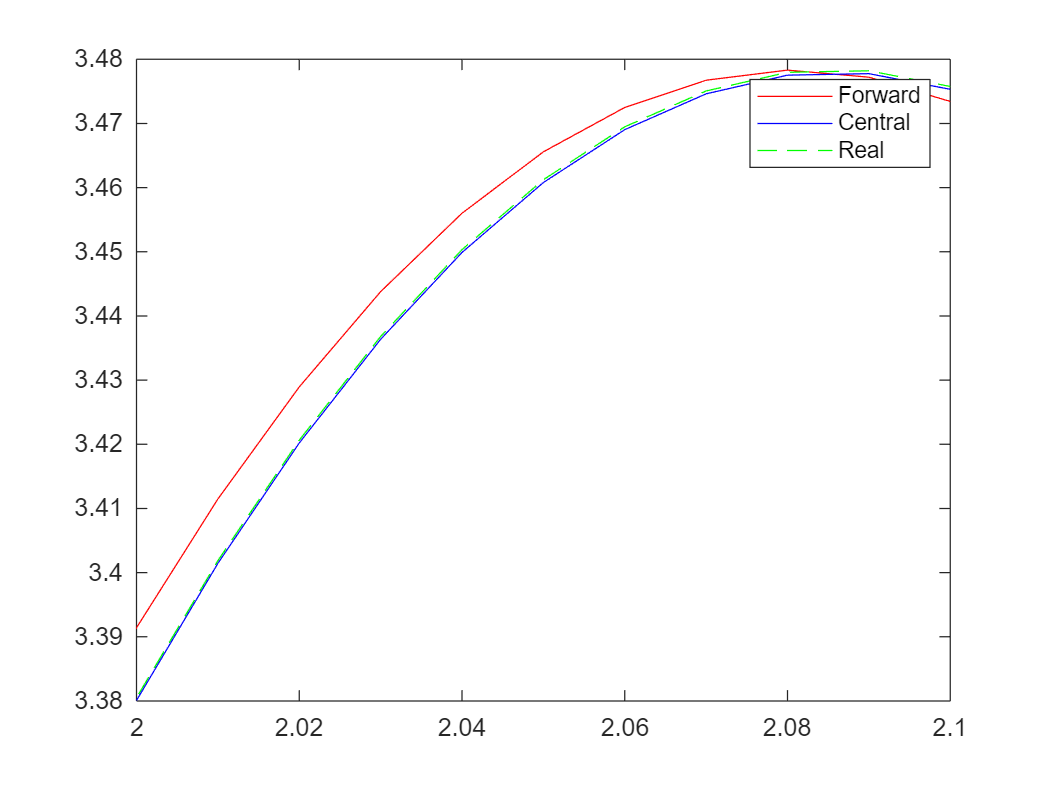

% Better to see the differences on a single plot with a zoomed in plot
figure
plot(x(1:end-1),dFForward1,'r')
hold on
plot(x(2:end-1),dFCentral1,'b')
plot(x,df(x),'--g')
legend('Forward','Central','Real')
xlim([2 2.1])

Question 2 (25%): 

a) (10%) Solve and plot the following ordinary differential equation using the Forward Euler’s Method

$\frac{dy}{dt}=y-2y^2$ , y(0) = 2

from $t=0$ to $t=3$ using a step size of $h=0\ldotp 1\ldotp$ Also, plot the true analytical solution (either solve by hand or use online resources such as Wolfram Alpha, Symbolab, etc) and include labels and a legend.

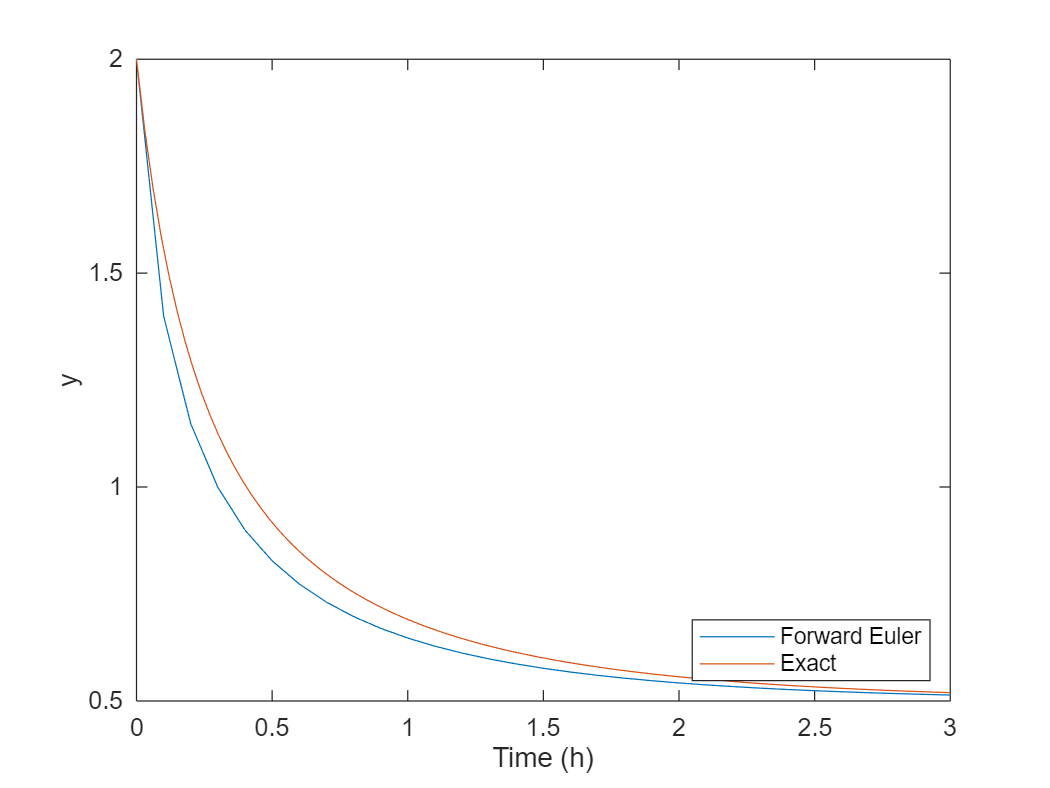

clear,clc,close all
% Parameters
ti=0;
tf=3;
h=0.1;

% Vector for t for Forward Euler
x=ti:h:tf;
% Smooth vector for real solution
xx=linspace(ti,tf);
% Actual Solution, you can find this by hand by noticing this is a
% Bernoulli Equation or noticing partial fraction decomposition can be used
df = @(t) 2*exp(t)./(4*exp(t)-3);

% Initial condition
y=zeros(1,length(x));
y(1)=2;
% Loop through all possible t values except the last
for ii=1:length(x)-1
    % Apply Forward Euler Formula of yNew=f(xold)*deltaX+yOld I directly
    % put the function in this case to show you another method of solving
    % it instead of using an anonymous function
    y(ii+1)=(y(ii)-2*y(ii)^2)*h+y(ii);
end
% Plot results
plot(x,y,'-','markersize',4) % Forward Euler
hold on
plot(xx,df(xx)) % Exact solution
hold off
ylabel("y");
xlabel("Time (h)");
legend('Forward Euler','Exact',"Location","southeast")

b) (5%) Show the absolute error of the above approximation for y(2).

% Find the index in the vector t where it is equal to 2.
ind_int=find(x==2);
% Calculate the absolute error
abs_error=abs(y(ind_int)-df(2))

abs_error = 0.0144

c) (10%) Plot the convergence from h =${10}^{-4}$ to h =${10}^{-2}$ for y(2).

% Step sizes to test
h_values = logspace(-4,0) % step size

h_values =     0.0001    0.0001    0.0001    0.0002    0.0002    0.0003    0.0003    0.0004    0.0004    0.0005    0.0007    0.0008    0.0010    0.0012    0.0014    0.0017    0.0020    0.0024    0.0029    0.0036    0.0043    0.0052    0.0063    0.0075    0.0091    0.0110    0.0133    0.0160    0.0193    0.0233    0.0281    0.0339    0.0409    0.0494    0.0596    0.0720    0.0869    0.1048    0.1265    0.1526    0.1842    0.2223    0.2683    0.3237    0.3907    0.4715    0.5690    0.6866    0.8286    1.0000


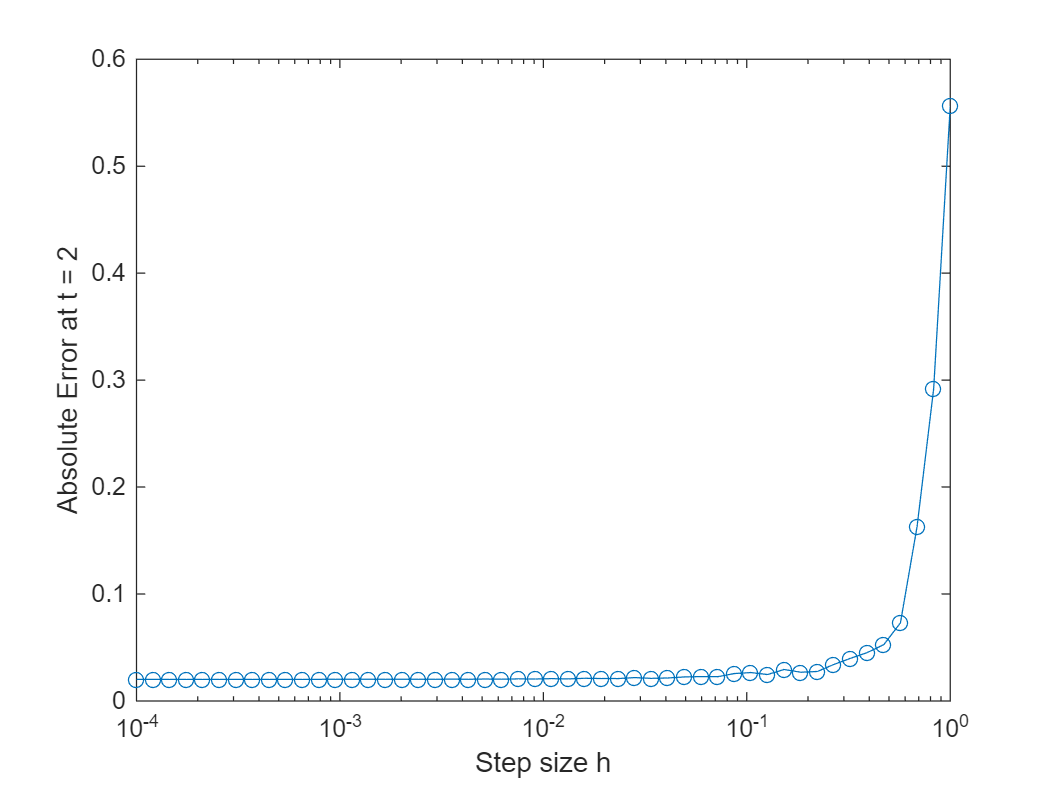

% Pre-allocation
errors_forward = zeros(size(h_values));
% True solution at t = 3
y_true = @(t) 2*exp(t)./(4*exp(t)-3);
y_exact = y_true(2);
% End time, might as well stop the solver right at the point of interest
t_end = 2; 
% Function f(t, y) = y-2*y^2
f=@(t,y) y-2*y^2;
% Loop over different step sizes
for ii = 1:length(h_values)
    h = h_values(ii);    % Current step size
    t = 0:h:t_end;      % Time vector
    % Preallocate solution vectors
    y_forward = zeros(1, length(t));
    % Initial conditions
    y_forward(1) = 1;
    % Forward Euler Method (explicit)
    for jj = 1:length(t)-1
        y_forward(jj+1) = y_forward(jj) + h * f(t(jj),y_forward(jj));
    end
    % Calculate absolute errors at t = 2 and save it
    errors_forward(ii) = abs(y_exact - y_forward(end));
end
% Plot convergence
figure;
semilogx(h_values, errors_forward, '-o');
xlabel('Step size h');
ylabel('Absolute Error at t = 2');

Question  3 (20%): 

a) (10%) Solve the following ordinary differential equation using the Backward Euler’s Method.

$\frac{dy}{dt}=-y^3$, y(0)=1

from t=0 to t=3 using a step size of h=0.1

clear,clc,close all
% (y(i)-y(i-1))/h = -y(i)^3 -> (y(i+1)-y(ii))/h = -y(i+1)^3
% y(i+1)=(-y(i+1)^3)*h+y(ii) 0=(-y(i+1)^3)*h+y(ii) - y(i+1)
% 0=(-Y^3)*h+y(ii)-Y Parameters
ti=0;
tf=3;
h=0.1;

% Vector for t
x=ti:h:tf;
% Actual Solution using Separation of Variables
df = @(t) 1./sqrt(2*t+1);

% Initial condition
y=zeros(1,length(x));
y(1)=1;
% Loop through all possible t values except the last
for ii=1:length(x)-1
    % Apply Backward Euler Formula I directly put the function in this case
    % to show you another method of solving it instead of using an
    % anonymous function Here's how you arrive at the equation starting
    % with the original diff eq 
    % dy/dt = -y^3 = -y(ii)^3 
    % Apply Backward Euler Scheme (y(ii)-y(ii-1))/h = -y(ii)^3
    % Shift indices forward by 1
    % (y(ii+1)-y(ii))/h = -y(ii+1)^3 
    % Shift terms around and subtract to get 0 on left side 
    % 0=(-y(ii+1)^3)*h+y(ii) - y(ii+1) 
    % Replace y(ii+1) with the argument Y for fzero  
    % 0=(-Y^3)*h+y(ii)-Y 
    % Initial guess is y(ii)
    y(ii+1)=fzero(@(Y) (-Y^3)*h+y(ii)-Y,y(ii));
end

b) (10%)  Find the analytical solution (either solve by hand or use online resources such as Wolfram Alpha, Symbolab, etc) and plot it against the result from (a).

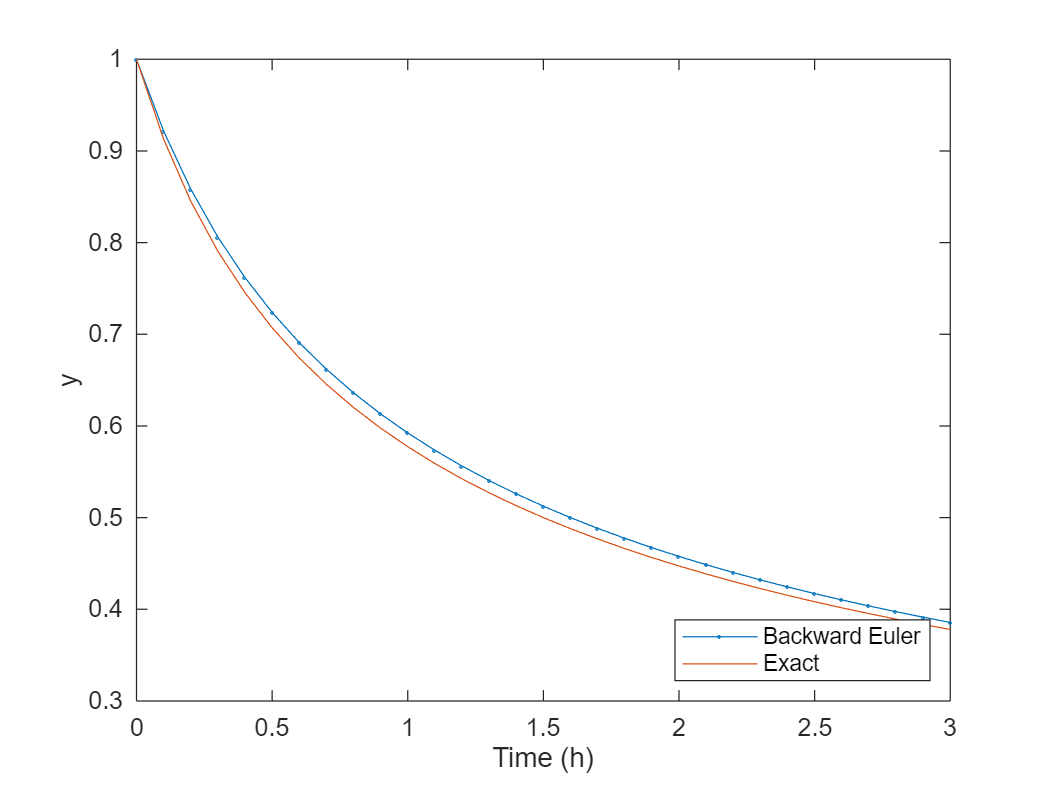

% Plot results
figure
plot(x,y,'-o','markersize',1) % Backward Euler
hold on
plot(x,df(x)) % Exact solution
hold off
ylabel("y");
xlabel("Time (h)");
legend('Backward Euler','Exact',"Location","southeast")

Question 4(15%)

For the following system:


$$\begin{array}{c}
\frac{dy_{{\left(1\right)}} }{dt}=y_{{\left(1\right)}} +5y_{{\left(2\right)}} \\
\frac{dy_{{\left(2\right)}} }{dt}={3y}_{{\left(1\right)}} \;\;-y_{{\left(2\right)}} 
\end{array}$$



$$y_{{\left(1\right)}} {\left(0\right)}=2,y_{{\left(2\right)}} {\left(0\right)}=3$$


a) (10%) Solve the system of differential equations and plot it from 0 to 3.

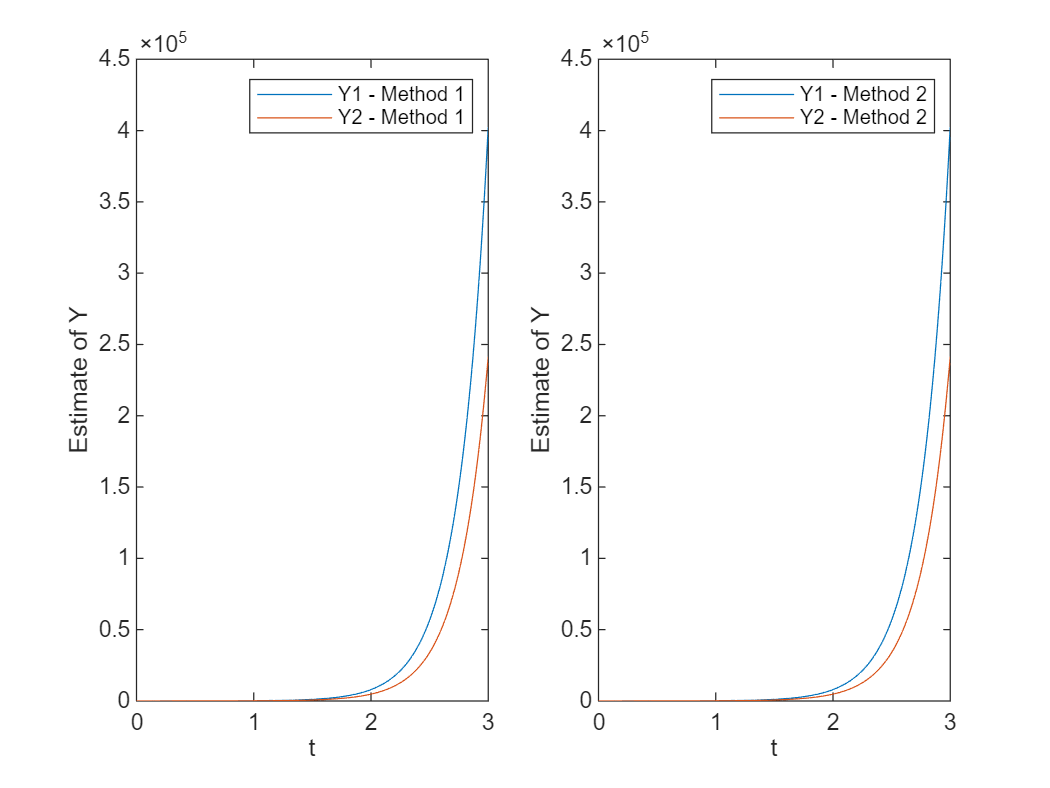

% Coupled ODEs

% Define the system with y(1) and y(2) being inputs relating to each
% equation
dy1 = @(t,y)  y(1) + 5*y(2);
dy2 = @(t,y)  3*y(1) - y(2) ;

% Parameters Step size
h = 0.01;
% Time vector from 0 to 3
x = 0:h:3;

% Method 1 Initial conditions, need 2 since we have 2 equations and they
% must be a column vector. The first element, Y(1) is the first equation
% and Y(2) is for the second equation. Each have their own row vector.
Y = zeros(2,length(x));
Y(:,1) = [2; 3];

% Loop through all possible t values except the last
for k=1:length(x)-1
    % Forward Euler applied to each equation
    Y(1,k+1) = Y(1,k) + h*dy1(x(k+1),Y(1:2,k));
    Y(2,k+1) = Y(2,k) + h*dy2(x(k+1),Y(1:2,k));
end

% Method 2 Initial conditions. Each one is given its own variable.
Y1Out=zeros(1,length(x));
Y1Out(1)=2;
Y2Out=zeros(1,length(x));
Y2Out(1)=3;
% Loop through all possible t values except the last
for k=1:length(x)-1
    % Forward Euler applied to each equation. In this case I apply the
    % formulas directly without an anonymous function
    Y1Out(k+1) = Y1Out(k) + h*(Y1Out(k)+5*Y2Out(k));
    Y2Out(k+1) = Y2Out(k) + h*(3*Y1Out(k)-Y2Out(k));
end

% Plot results
figure
subplot(1,2,1)
plot(x,Y)
xlabel('t'); ylabel('Estimate of Y')
legend('Y1 - Method 1','Y2 - Method 1')
subplot(1,2,2)
plot(x,Y1Out)
hold on
plot(x,Y2Out)
xlabel('t'); ylabel('Estimate of Y')
legend('Y1 - Method 2','Y2 - Method 2');

b) (5%) Find the value at $Y{\left(2\ldotp 5\right)}={\left[\begin{array}{c}
?\\
?
\end{array}\right]}$.

Y(1:2,x==2.5)

ans = 1.0e+04 *

    5.6648
    3.3989


Question 5 (25%)

Constrained population growth of bacteria and amoebae is governed by the following:

- The amoebae will decrease by 150% if left undisturbed.

- The bacteria will increase by 80% if left undisturbed. 

- The amoebae will eat the bacteria reducing their, the bacteria's, numbers by 30%.

- The amoebae will increase by 20% when bacteria are present.

a) (20%) Model the system by converting the above statements into differential equations, one for amoebae and another for bacteria. Then, solve and plot it over 4 hours. The initial amount of bacteria is 5 billion and of amoebae is 1 billion. Use a step size of 0.01.

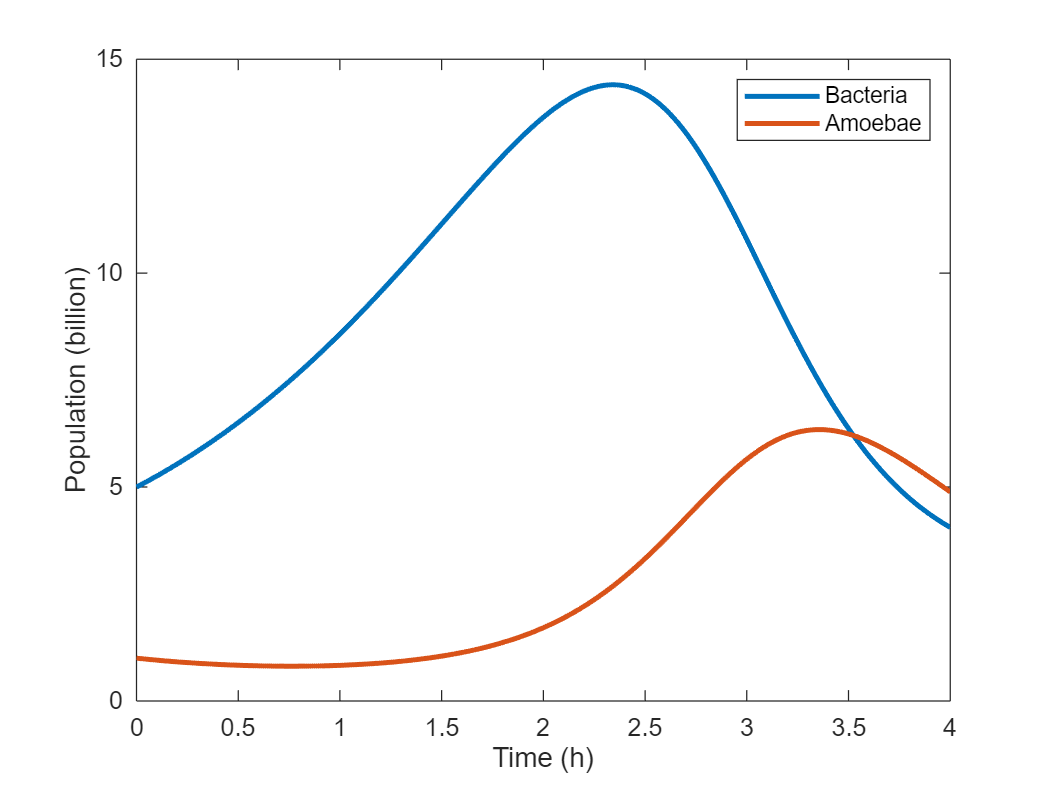

clear
% Initial populations (billions)
P0Bac = 5;
P0Amo= 1;

h = 0.01;           % Small time step to ensure stability
x = 0:h:4;          % Time vector

% Store populations and seed with initial conditions
Pbac = zeros(1,length(x));
Pbac(1) = P0Bac;
Pamo = zeros(1,length(x));
Pamo(1) = P0Amo;

% The coupled ODE system with the first argument being pb and second being
% pa. You should have as many arguments as you have equations. You may also
% have a 3rd argument for your independent variable, such as time, if it is
% used in your equations.

dPbac= @(pb,pa)  0.8*pb - 0.3*pb*pa;
dPamo = @(pb,pa) -1.5*pa + 0.2*pb*pa;

% % Loop through all possible t values except the last
for k = 1:length(x)-1
    % Simulate bacteria population
    Pbac(k+1) = Pbac(k) + h*dPbac(Pbac(k),Pamo(k));
    % Simulate amoeba population
    Pamo(k+1) = Pamo(k) + h*dPamo(Pbac(k),Pamo(k));
end

figure
plot(x,Pbac,x,Pamo,'linewidth',2);
xlabel('Time (h)')
ylabel('Population (billion)')
legend('Bacteria','Amoebae')

b) (5%) Find the time when the bacteria population is at its maximum.

% Parse the time vector, t, for when the maximum value of Pbac occurs and
% then find the index where it happens.
x(Pbac==max(Pbac))

ans = 2.3400